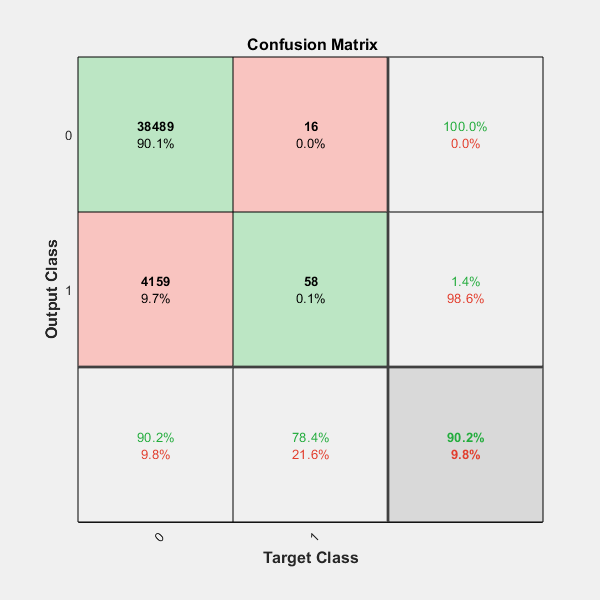

clc
clear

ds = readmatrix('umap_train_cc.csv');
% filepath="C:\Users\ezsun\Documents\MATLAB\machin learning\A2_Training_Input_Output_Data.xlsx";
% ds = readmatrix(filepath);

input_node_cnt= 3;              % # of input nodes
hiden_layer_neuron= [200 150 20] ;      % # of hidden layer nodes
layers_in_hidden= length(hiden_layer_neuron);
output_node_cnt=2;              % # of output nodes


% Generate random weight
mu = 0;
% wight Initialization 
w_hidden=cell(1,layers_in_hidden);                                          % weights of 1st hidden layer
sigma = (input_node_cnt+1)^-0.5;
pd = makedist('Normal','mu',mu,'sigma',sigma);
w_hidden{1,1}= random(pd,hiden_layer_neuron(1),input_node_cnt+1);        
% w_hidden{1}=ones(hiden_layer_neuron(1),input_node_cnt+1);
for i=2 : layers_in_hidden
    sigma = (hiden_layer_neuron(i-1)+1)^-0.5;
    pd = makedist('Normal','mu',mu,'sigma',sigma);
    w_hidden{i}= random(pd,hiden_layer_neuron(i),hiden_layer_neuron(i-1)+1);  
%     w_hidden{i}= ones(hiden_layer_neuron(i),hiden_layer_neuron(i-1)+1);
end


sigma = (hiden_layer_neuron(layers_in_hidden)+1)^-0.5;
pd = makedist('Normal','mu',mu,'sigma',sigma);
w_output= random(pd,output_node_cnt,hiden_layer_neuron(layers_in_hidden)+1);                 % weights of output layer
% w_output= ones(1,hiden_layer_neuron(layers_in_hidden)+1);


rand_index=randperm(size(ds,1));  % Gnerate randam index
ds=ds(rand_index,:);              % Shuffle the datasourse

ds(:,5)=1-ds(:,4);  % add output for softmax
input= ds(:,1:3)';
yd= ds(:,4:5)';
% input= ds(1:398041,1:3)';
% yd= ds(1:398041,4:5)';

% v_input= ds(398042:483336,1:3)';
% v_yd= ds(398042:483336,4:5)';

ds = readmatrix('umap_test_cc.csv');
ds(:,5)=1-ds(:,4);  % add output for softmax

t_input= ds(:,1:3)';
t_yd= ds(:,4:5)';

% input= ds(1:398041,1:3)';
% yd= ds(1:398041,4)';
% 
% v_input= ds(398042:483336,1:3)';
% v_yd= ds(398042:483336,4)';
% 
% t_input= ds(483337:568630,1:3)';
% t_yd= ds(483337:568630,4)';


% Early stopping
v1=100003;
v2=100002;
new_val_error=100001;
itercnt=0;                    % iteration #
epoch= 100;                   % iteration per training
record_e=[];
record_iter=[];


[e, w_hidden, w_output]= MLP(input,yd,epoch,w_hidden,w_output);
% while v2-v1>0.001 || v1-new_val_error>0.001 
% 
%     [e, w_hidden, w_output]= MLP(input,yd,epoch,w_hidden,w_output);
%     itercnt=itercnt+1;
%     [v_e]=MlPforward(v_input, v_yd,w_hidden,w_output)    % go forward get error
%     v2=v1;
%     v1=new_val_error;
%     new_val_error=v_e;
% 
%     record_e=[record_e, v_e];
%     record_iter=[record_iter, itercnt];
% 
% end
% plot(record_iter, record_e);
% res=e
% w_hidden{:}

[t_e,t_output]=MlPforward(t_input, t_yd,w_hidden,w_output);
% t_output(find(t_output>0.5))=1;
% t_output(find(t_output<=0.5))=0;
for i=1 : size(t_output,2)
    if t_output(1,i)>= t_output(2,i)
        t_output(1,i)=1;
        t_output(2,i)=0;
    else
        t_output(1,i)=0;
        t_output(2,i)=1;
    end
end
plotconfusion(t_yd(1,:), t_output(1,:));

function  [e, w_hidden, w_output]= MLP(input, yd,iter,w_hidden,w_output)
bias= 1;
alfa= 0.1;           % learning rate
activation = @(x) 1./(1+exp(-x));      % sigmoid for hidder neuron
derivative = @(x) x.*(1-x);           
% activation_o = @(x) 1./(1+exp(-x));     % sigmoid for output
% derivative_o = @(x) x.*(1-x); 
% activation_o = @(x) x;                  % linear for output
% derivative_o = @(x) 1;
activation_o = @(x) exp(x)./sum(exp(x));     % softmax for output 
derivative_o = @(x) 1; 

cnt=size(input);
input= [bias*ones(1, cnt(2)); input];    % add bias

for i =1: iter
    %% forward    
    y_hidden= cell(1, length(w_hidden));
    y_hidden{1} = [bias*ones(1, cnt(2)); activation(w_hidden{1} * input)];
    for j=2: length(w_hidden)
        y_hidden{j} = [bias*ones(1, cnt(2)); activation(w_hidden{j} * y_hidden{j-1})];
    end

    y_output= activation_o(w_output * y_hidden{end});

%     sh=0.5;
%     y_output(find(y_output>sh))=1;
%     y_output(find(y_output<=sh))=0;


    %minimum mean square error
%     e= 0.5* sum(( yd- y_output).^2)/cnt(2);

    %cross entropy error
    e= -sum(log(y_output).*yd);

    % L2 regularization 
    lambda=0.1;
    e= e + lambda/(2* (size(input,1)-1)) * (sum(cellfun(@(w) sum(w(2:end).^2), w_hidden))+ sum(w_output(2:end).^2));

    % backward
    deltas=cell(1,length(w_hidden)+1);
    deltas{end}= (-(yd-y_output)).* derivative_o(y_output)/cnt(2);
    deltas{end-1}= (w_output(:, 2:1:end)'*deltas{end}) .*derivative(y_hidden{end}(2:1:end,:));
    for j=length(deltas)-2 : -1: 1
        deltas{j}=(w_hidden{j+1}(:, 2:1:end)'*deltas{j+1}).* derivative(y_hidden{j}(2:1:end,:));
    end

% update weights
%     w_output= w_output- alfa* deltas{end}* y_hidden{end}';
    tmp=w_output;
    tmp(:,1)=0;
    w_output= w_output- alfa* (deltas{end}* y_hidden{end}' +  lambda/((size(input,1)-1)).*tmp);     % with L2 regularization
    for j =length(w_hidden):-1:2
%         w_hidden{j}= w_hidden{j}- alfa* deltas{j}* y_hidden{j-1}';
        tmp=w_hidden{j};
        tmp(:,1)=0;
        w_hidden{j}= w_hidden{j}- alfa* (deltas{j}* y_hidden{j-1}'+ lambda/((size(input,1)-1)).*tmp); % with L2 regularization
    end
%     w_hidden{1}= w_hidden{1}- alfa* deltas{1}* input';
    tmp=w_hidden{1};
    tmp(:,1)=0;
    w_hidden{1}= w_hidden{1}- alfa* (deltas{1}* input'+ lambda/((size(input,1)-1)).*tmp);
end
end



function  [e, y_output,w_hidden, w_output]= MlPforward(input, yd,w_hidden,w_output)
bias= 1;

activation = @(x) 1./(1+exp(-x));      % sigmoid for hidder neuron    
% activation_o = @(x) 1./(1+exp(-x));     % sigmoid for output
% activation_o = @(x) x;                  % linear for output
activation_o = @(x) exp(x)./sum(exp(x));     % softmax for output 

cnt=size(input);
input= [bias*ones(1, cnt(2)); input];    % add bias
%% forward    
y_hidden= cell(1, length(w_hidden));
y_hidden{1} = [bias*ones(1, cnt(2)); activation(w_hidden{1} * input)];
for j=2: length(w_hidden)
    y_hidden{j} = [bias*ones(1, cnt(2)); activation(w_hidden{j} * y_hidden{j-1})];
end
y_output= activation_o(w_output * y_hidden{end});
% sh=0.5;
% y_output(find(y_output>sh))=1;
% y_output(find(y_output<=sh))=0;

e= 0.5* sum(( yd- y_output).^2)/cnt(2);
end